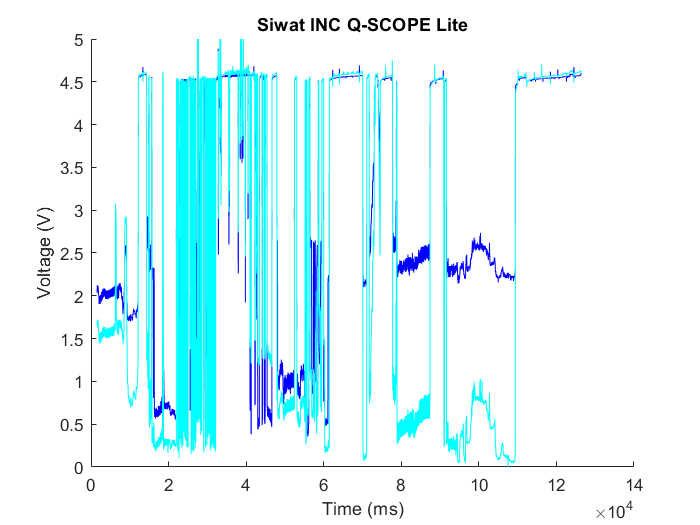

Error reading data from the serial port.
Transport object has become invalid.

osc = serialport("COM4",115200);
configureTerminator(osc,"CR");
datastore = table();
hold on;
title("Siwat INC Q-SCOPE Lite")
xlabel("Time (ms)");
ylabel("Voltage (V)");
while true
    data=readline(osc);
    try
    jsondata=jsondecode(data);
    temp = {jsondata.timestamp*7.9,(jsondata.CH1+1)/204.8,(jsondata.CH2+1)/204.8};
    datastore = [temp;datastore];
    ptplot = plot(datastore.b1,datastore.b2,datastore.b1,datastore.b3);
    set(ptplot, {'color'}, num2cell(jet(2),2));
    catch exception
        
    end
end